function dstate_dt = dynamics(state, forces, params)
    % Unpack parameters and state for clarity
    mq = params.mq;
    mb = params.mb;
    ms = params.ms;
    L = params.L;
    Ixx = params.Ixx;
    g = params.g;
    r = params.r;
    
    y = state(1);
    z = state(2);
    phi = state(3);
    theta = state(4);
    y_d = state(5);
    z_d = state(6);
    phi_d = state(7);
    theta_d = state(8);

    Fl = forces(1);
    Fr = forces(2);
  
    Ip = ms*L^2/3+mb*L^2;
    Lcg = L*(ms/2+mb)/(ms+mb);
    
    % A*x_dd = B
    
    A = [ms+mb+mq 0 (ms+mb)*Lcg*cos(phi+theta) (ms+mb)*Lcg*cos(phi+theta);
        0 ms+mb+mq (ms+mb)*Lcg*sin(phi+theta) (ms+mb)*Lcg*sin(phi+theta);
        Lcg*cos(phi+theta)*(ms+mb) Lcg*sin(phi+theta)*(ms+mb) Ip Ip;
        0 0 Ixx 0];
    
    B = [(Fl+Fr)*sin(phi)+(ms+mb)*Lcg*sin(phi+theta)*(phi_d+theta_d)^2 ;
        (Fl+Fr)*cos(phi)-(ms+mb)*Lcg*cos(phi+theta)*(phi_d+theta_d)^2-g*(ms+mb+mq) ;
        -g*Lcg*(ms+mb)*sin(phi+theta) ; 
        (Fr-Fl)*r];
    
    state_dd = inv(A)*B;

    x_d = [y_d ; z_d ;phi_d ;theta_d; state_dd];

    dstate_dt = [y_d ; z_d ;phi_d ;theta_d; state_dd];
end

function [time, state_history] = run_simulation(initial_state, Fl_history, Fr_history, T, N, params)
    dt = T / N;
    time = linspace(0, T, N+1)';
    state_history = zeros(N+1, length(initial_state));
    state_history(1, :) = initial_state;
    
    current_state = initial_state(:); % Ensure it's a column vector
    
    for k = 1:N
        forces = [Fl_history(k); Fr_history(k)];
        
        % This is your dynamics function (e.g., from your existing code)
        dstate_dt = dynamics(current_state, forces, params); 
        
        % Simple Euler integration step
        current_state = current_state + dstate_dt * dt;
        state_history(k+1, :) = current_state';
    end
end

function [J, c, ceq] = objectiveAndConstraints(x, initial_state, target_state, T, N, params)
    % 1. Unpack decision variables 'x' into force histories
    forces = reshape(x, [2, N])'; % Reshape to an N x 2 matrix
    Fl_history = forces(:, 1);
    Fr_history = forces(:, 2);

    % 2. Run the simulation
    [~, state_history] = run_simulation(initial_state, Fl_history, Fr_history, T, N, params);

    % 3. Calculate Objective Function (J)
    % Minimize the sum of the control effort squared over the trajectory.
    dt = T / N;
    J = sum(Fl_history.^2 + Fr_history.^2) * dt;

    % 4. Calculate Inequality Constraints (c <= 0) - UNCHANGED
    z_history = state_history(:, 2); 
    z_initial = initial_state(2);
    z_upper_bound = z_initial * 1.10;
    z_lower_bound = z_initial * 0.90;

    % fmincon requires c(x) <= 0
    c1 = z_history - z_upper_bound;
    c2 = z_lower_bound - z_history;
    c = [c1; c2];

    % This hard constraint is now solely responsible for reaching the target.
    final_state = state_history(end, :);
    ceq = final_state(:) - target_state(:);
end

function [c, ceq] = constraint_wrapper(x, initial_state, target_state, T, N, params)
    [~, c, ceq] = objectiveAndConstraints(x, initial_state, target_state, T, N, params);
end

function J = objective_wrapper(x, initial_state, target_state, T, N, params)
    [J, ~, ~] = objectiveAndConstraints(x, initial_state, target_state, T, N, params);
end


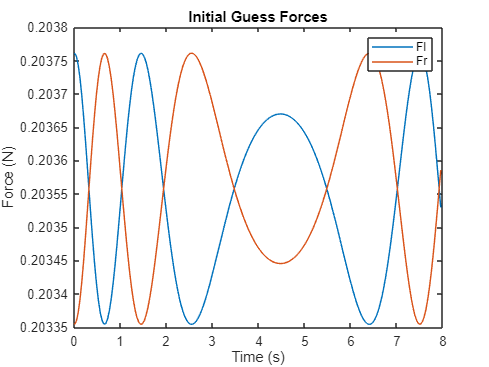

clear; clc; close all;

% --- 1. Define System Parameters ---
params.mq = 0.029; % kg
params.mb = 0.01; % kg
params.ms = 0.0025; % kg
params.L = 0.3; % m
params.Ixx = 6.410179e-06; % kg m2
params.g = 9.81; % kg/m2
params.r = 0.05665/2; % m

% params.m = 0.03;   % kg
% params.g = 9.81; % m/s^2
% params.Ixx = 6.41e-6; % kg*m^2
% params.L = 0.05;   % m (distance from center to thruster)

% --- 2. Define Problem Setup ---
T = 8.0; % Total maneuver time in seconds
N = 200;  % Number of discretization steps

% Define initial and target states based on a 6-state vector
% [y, z, theta, y_dot, z_dot, theta_dot]
y_initial = 0;
z_initial = 1.0;
initial_state = [y_initial, z_initial, 0, 0, 0, 0, 0, 0];
target_state  = [y_initial, z_initial, 0, pi/4, 0, 0, 0, 0]; % 180 deg = pi radians

% --- 3. Setup for fmincon ---
n_vars = 2 * N;

% Bounds
max_force = 0.3; % Newtons
lb = zeros(n_vars, 1);
ub = max_force * ones(n_vars, 1);

% Initial Guess (crucial for convergence!)
% A good guess is constant thrust to counteract gravity, then small random perturbations
hover_force = ((params.ms+params.mb+params.mq) * params.g) / 2;
t_guess = linspace(0, T, N); % Time vector for the guess



% Create a sinusoidal nudge force
nudge_amplitude = hover_force * 0.001; % Try 50% of hover force
nudge_freq = sqrt(params.g/params.L)*1; % rad/s - you may need to tune this!
Fl_guess = hover_force + nudge_amplitude * chirp(t_guess, nudge_freq*0.9/(2*pi),3,nudge_freq*0.3/(2*pi));
Fr_guess = hover_force - nudge_amplitude * chirp(t_guess, nudge_freq*0.9/(2*pi),3,nudge_freq*0.3/(2*pi));

[time, state_guess] = run_simulation(initial_state, Fl_guess, Fr_guess, T, N, params);

figure;
plot(time(1:200),Fl_guess',time(1:200),Fr_guess')
title("Initial Guess Forces")
xlabel("Time (s)")
ylabel("Force (N)")
legend("Fl","Fr")

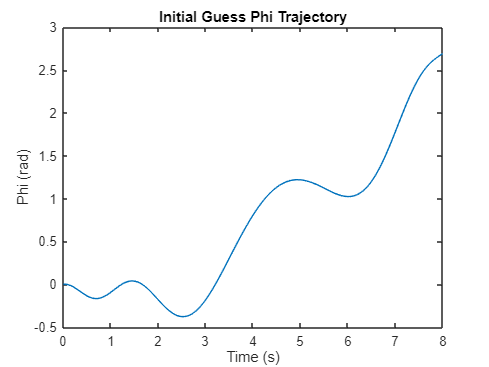


figure;
plot(time,state_guess(:,3))
title("Initial Guess Phi Trajectory")
xlabel("Time (s)")
ylabel("Phi (rad)")

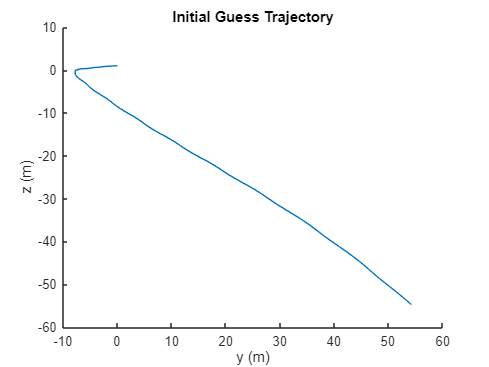


figure;
hold on
plot(state_guess(:,1),state_guess(:,2))
title("Initial Guess Trajectory")
xlabel("y (m)")
ylabel("z (m)")
hold off



% Interleave them into the x0 vector
x0 = zeros(n_vars, 1);
x0(1:2:end) = Fl_guess; % Odd elements are Fl
x0(2:2:end) = Fr_guess; % Even elements are Fr

% --- 4. Call fmincon ---
fprintf('Running fmincon...\n');

Running fmincon...


options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp', ...
                       'MaxFunctionEvaluations', 20000, 'MaxIterations', 1000, ...
                       'ConstraintTolerance', 1e-4, 'StepTolerance', 1e-8);

% Use an anonymous function to pass extra parameters to the objective function
objFun = @(x) objective_wrapper(x, initial_state, target_state, T, N, params);

nonlconFun = @(x) constraint_wrapper(x, initial_state, target_state, T, N, params);

[x_optimal, fval, exitflag, output] = fmincon(objFun, x0, [], [], [], [], lb, ub, nonlconFun, options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         401    6.629708e-01     6.202e+01     1.000e+00     0.000e+00     1.630e-02  
    1    


% --- 5. Process and Plot Results ---
if exitflag > 0
    fprintf('Optimization successful!\n');
    
    % Reshape optimal forces
    forces_opt = reshape(x_optimal, [2, N])';
    Fl_opt = forces_opt(:, 1);
    Fr_opt = forces_opt(:, 2);
    
    % Rerun simulation with optimal controls to get the final trajectory
    [time, state_opt] = run_simulation(initial_state, Fl_opt, Fr_opt, T, N, params);
    
    % Plotting
    figure;
    
    % Plot States
    subplot(2,1,1);
    plot(time, rad2deg(state_opt(:,4)), 'b-', 'LineWidth', 1);
    hold on;
    plot(time, (state_opt(:,2)));
    plot(time(end), rad2deg(target_state(4)), 'rx', 'MarkerSize', 10, 'LineWidth', 1);
    title('State Trajectories');
    ylabel('Angle (deg)');
    grid on;
    
    % You can add more state plots (y, z, etc.) here
    
    % Plot Controls
    subplot(2,1,2);
    stairs(time(1:end-1), Fl_opt, 'r-', 'LineWidth', 1);
    hold on;
    stairs(time(1:end-1), Fr_opt, 'g-', 'LineWidth', 1);
    title('Control Inputs (Forces)');
    xlabel('Time (s)');
    ylabel('Force (N)');
    legend('Fl (Left)', 'Fr (Right)');
    grid on;
    ylim([0, max_force * 1.1]);
else
    fprintf('Optimization failed. Exit flag: %d\n', exitflag);
end

